%write the starting and ending position
start_pos = 401872

start_pos = 401872

end_pos = (start_pos + 2000)

end_pos = 403872


%write the experiment state and the count (calculation / happy / sad )
state = "General_state" 

state = "General_state"

count = "7"

count = "7"


%calculation (0, 1, 2, .....)
%happy(0, 1, 2, .....)


%write the first three letters of your name
my_name_3 = "mjh"

my_name_3 = "mjh"


%write the name of the file (subject) you want to load
load_file_name = '17201075.txt'

load_file_name = '17201075.txt'



%%%Don't edit unless you know what you are doing
load_file_name_nofmt = erase(load_file_name,'.txt')

load_file_name_nofmt = '17201075'

file_name = state + "_" + load_file_name_nofmt+ "_" + my_name_3 + "_"+ count

file_name = "General_state_17201075_mjh_7"

file_name_csv = file_name + ".csv"

file_name_csv = "General_state_17201075_mjh_7.csv"

file_name_png = file_name + ".png"

file_name_png = "General_state_17201075_mjh_7.png"


x = load(load_file_name)

x =      0     0     0     0     0   432
     1     0     0     0     0   438
     2     0     0     0     0   445
     3     0     0     0     0   444
     4     0     0     0     0   435
     5     0     0     0     0   428
     6     0     0     0     0   423
     7     0     0     0     0   428
     8     0     0     0     0   438
     9     0     0     0     0   444



S=x(:,6);

s = S(start_pos:end_pos)

s =    789
   788
   777
   760
   739
   717
   701
   692
   686
   679


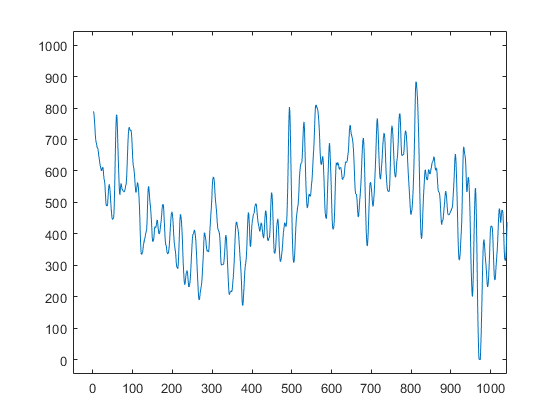

csvwrite(file_name_csv,s)

plot(s);

xlim([-50 1041])
ylim([-46 1045])
print(gcf,file_name_png,'-dpng','-r600');  